clc
clear all
%syms l M m_l I_psi I_theta I_phi I g
global beta
beta = 10;
constants = [.2 5 .5 .01 .01 .01 .5 9.81];
xin = 1;
yin = 0;
zin = 2;
xf = 0;
yf = 0;
zf = 0;

x_initial = zeros(16,1);
x_final = zeros(16,1);
x_initial(1) = xin;%%must have inital velocity
x_initial(2) = yin;
x_initial(3) = zin;
% x_initial(4) = deg2rad(6);

x_final(1) = xf;
x_final(2) = yf;
x_final(3) = zf;

lam_initial = zeros(16,1); %% initial guess for lamda
W1 = 0*eye(8);
W2 = 100*eye(8);
R = 1*eye(4);
%createODEFunc(W1, W2, R);
% tf_guess = 20;
solinit = bvpinit(linspace(0,20,100),[x_initial; lam_initial]);
options = bvpset("Stats","on","RelTol", 1e-12, 'AbsTol', 1e-12);
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
sol = bvp4c(@(t, inp)bvpode(t, inp, constants), @(ya, yb)bvpconst(ya, yb, x_initial, x_final), solinit, options);

The solution was obtained on a mesh of 892 points.
The maximum residual is  3.309e-01. 
There were 38234 calls to the ODE function. 
There were 506 calls to the BC function. 


t = sol.x';
y = sol.y';
% [t, y] = ode45(@(t, inp)bvpode(t, inp, constants), linspace(0, 20, 10000), [x_initial; lam_initial], opts);

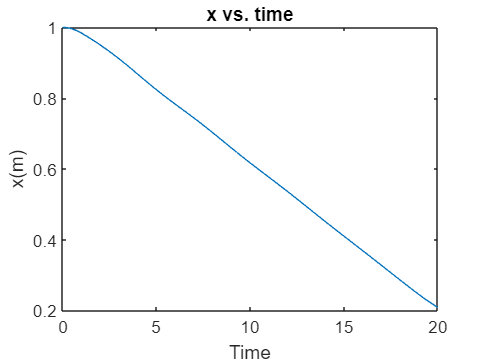

close all;
figure()
plot(t,y(:,1))
title("x vs. time");
xlabel("Time");
ylabel("x(m)");

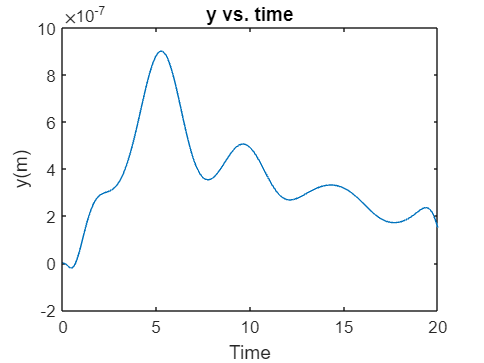


figure()
plot(t,y(:,2))
title("y vs. time");
xlabel("Time");
ylabel("y(m)");

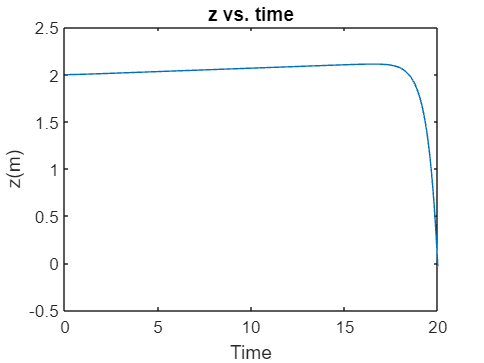



figure()
plot(t,y(:,3))
title("z vs. time");
xlabel("Time");
ylabel("z(m)");

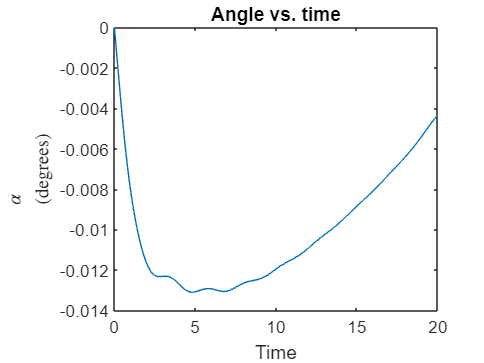



figure()
plot(t,y(:,4)*180/pi)
title("Angle vs. time");
xlabel("Time");
ylabel("$${\alpha}$$(degrees)",Interpreter="latex");

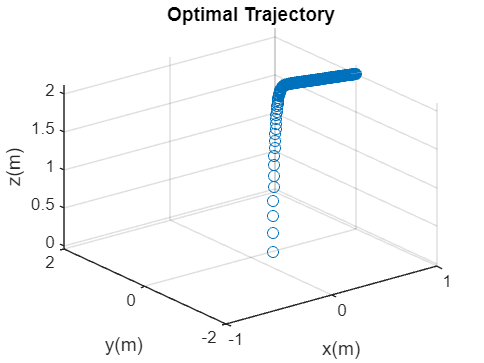



figure()
scatter3(y(:, 1), y(:, 2), y(:, 3));
title("Optimal Trajectory");
xlabel("x(m)");
ylabel("y(m)");
zlabel("z(m)");
xlim([-1 1])
ylim([-2 2])

%zlim([0])

beta = 100;
solinit = bvpinit(linspace(0,20,100),[x_initial; lam_initial]);
options = bvpset("Stats","on","RelTol", 1e-12, 'AbsTol', 1e-12);
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
sol = bvp4c(@(t, inp)bvpode(t, inp, constants), @(ya, yb)bvpconst(ya, yb, x_initial, x_final), solinit, options);

The solution was obtained on a mesh of 892 points.
The maximum residual is  3.414e-01. 
There were 48121 calls to the ODE function. 
There were 587 calls to the BC function. 


t2 = sol.x';
y2 = sol.y';
% [t, y] = ode45(@(t, inp)bvpode(t, inp, constants), linspace(0, 20, 10000), [x_initial; lam_initial], opts);

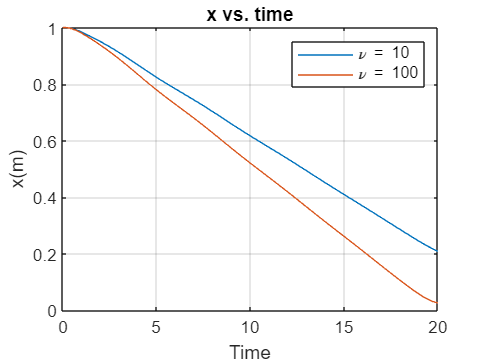

figure()
plot(t,y(:,1))
hold on
plot(t2,y2(:,1))
grid on
legend("{\nu} = 10","{\nu} = 100")
title("x vs. time");
xlabel("Time");
ylabel("x(m)");

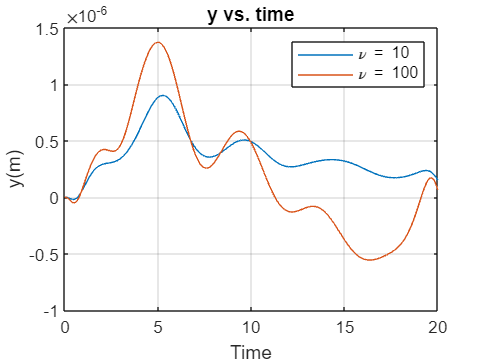


figure()
plot(t,y(:,2))
hold on
plot(t2,y2(:,2))
grid on
legend("{\nu} = 10","{\nu} = 100")

title("y vs. time");
xlabel("Time");
ylabel("y(m)");

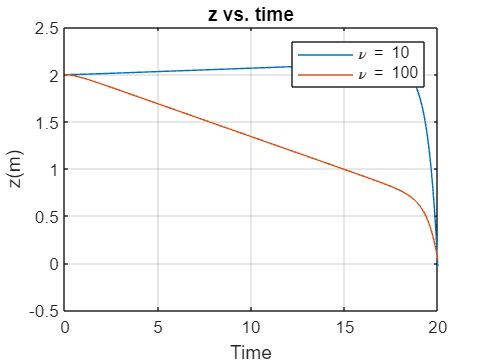



figure()
plot(t,y(:,3))
hold on
plot(t2,y2(:,3))
title("z vs. time");
grid on
legend("{\nu} = 10","{\nu} = 100")

xlabel("Time");
ylabel("z(m)");

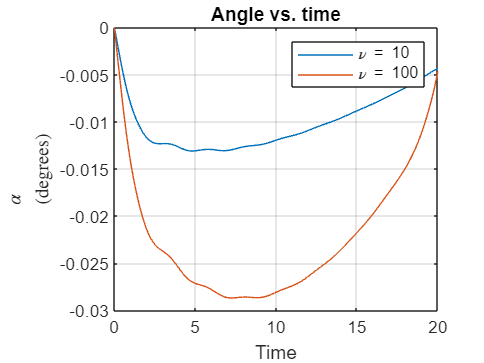



figure()
plot(t,y(:,4)*180/pi)
hold on
plot(t2,y2(:,4)*180/pi)
title("Angle vs. time");
grid on
legend("{\nu} = 10","{\nu} = 100")

xlabel("Time");
ylabel("$${\alpha}$$(degrees)",Interpreter="latex");

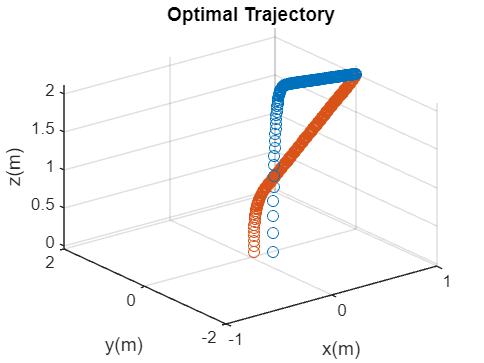



figure()
scatter3(y(:, 1), y(:, 2), y(:, 3));
hold on
scatter3(y2(:, 1), y2(:, 2), y2(:, 3));
grid on
%legend("{\beta} = 10","{\beta} = 100")
title("Optimal Trajectory");
xlabel("x(m)");
ylabel("y(m)");
zlabel("z(m)");
xlim([-1 1])
ylim([-2 2])

%zlim([0])